# Solving the 1st Order Linear ODEs using Midpoint(Polygon) Method

*MohammadSina GhanbariPakdehi, Chemical and Petroleum Engineering Department, Fall 2021*

The "Differential Equation Midpoint Method" is a computational technique employed for approximating solutions to first-order ordinary differential equations (ODEs). In cases where obtaining an exact analytical solution is challenging or unattainable, numerical methods like the Midpoint Method offer a practical means of estimating the solution. This method is grounded in the midpoint rule, a numerical integration technique. The provided code exemplifies the application of the Midpoint Method through MATLAB, utilizing user-provided inputs such as the differential equation, the range of independent variable values, and initial conditions. By iteratively computing midpoint values and updating the dependent variable, the code produces an approximation of the solution to the given ODE within the specified range. Through this code, the mechanics of the Midpoint Method and its utility in solving ODEs come to light.

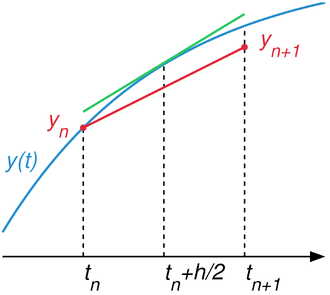

*Illustration of the midpoint method assuming that *$y_n$* equals the exact value *$y\left(t_n \right)$*. The midpoint method computes *$y_{n+1}$* so that the red chord is approximately parallel to the tangent line at the midpoint (the green line). *[*Source*](https://en.wikipedia.org/wiki/Midpoint_method)

Each 1st order ODE can be showed as a function of dependent variables. for example:


$$\frac{\mathrm{dy}}{\mathrm{dx}}=x+y=f\left(x,y\right)$$


The iterative method is showed as follows:

$y_{n+1} =y_n +h\ldotp f\left(x_n +\frac{h}{2},y_n +\frac{h}{2}\ldotp f\left(x_n ,y_n \right)\right)$ - Explicit form

$y_{n+1} =y_n +h\ldotp f\left(x_n +\frac{h}{2},\frac{1}{2}\left(y_n +y_{n+1} \right)\right)$ - Implicit form

### Part1: Input data

clear, clc
syms x y
f = input('Enter the equation of f(x,y): ');    
X = input('Enter the range of xi as a vector: ');
Y = ones(1, length(X));  % initial value of yi vector
X(1, 1) = input('Enter the value of x0: ');     % Value of x0
Y(1, 1) = input('Enter the value of y0: ');     % Value of y0
h = (X(2) - X(1)) / (length(X) - 1);            % Step Length

### Part2: ODE Calculation

for i = 2:length(X)
    x_mid = X(i - 1) + 0.5 * h;
    y_mid = Y(i - 1) + 0.5 * h * subs(f, [x, y], [X(i - 1), Y(i - 1)]);
    
    Y(i) = Y(i - 1) + h * subs(f, [x, y], [x_mid, y_mid]);
end
Xi = X';
Yi = Y';
i = (0:(length(X)-1))';

### Part3: Results & Visualization

result = table(i,Xi,Yi);
disp('The results of calculation are:'), disp(result)

The results of calculation are:
    i     Xi       Yi  
    __    ___    ______

     0      0         1
     1    0.2    1.0204
     2    0.4    1.0453
     3    0.6    1.0746
     4    0.8    1.1087
     5      1    1.1474
     6    1.2     1.191
     7    1.4    1.2395
     8    1.6     1.293
     9    1.8    1.3517
    10      2    1.4155



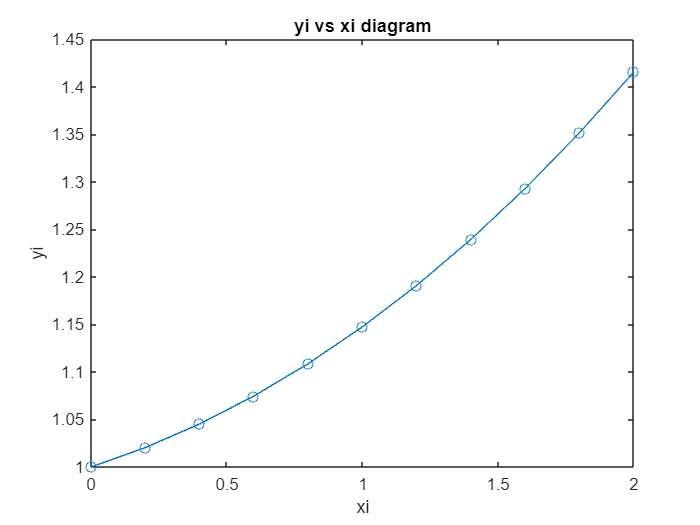

plot(X, Y, '-o')
xlabel('xi')
ylabel('yi')
title('yi vs xi diagram')